# Parse .hmod Files

Suppose you have KS_JEDC10.hmod in the working directory. Call

clear_hans
hans KS_leading

Parsing...ok!
Compiling dpopt_vfi
Building with 'MinGW64 Compiler (C++)'.
MEX completed successfully.


ans = struct with fields:
               parameters: {'beta'  'w'  'r'}
                var_shock: 'e'
                var_state: 'k'
              var_pre_vfi: {1×0 cell}
               var_policy: {'c'  'kp'}
                  var_aux: {1×0 cell}
                  var_agg: 'K'
            var_agg_shock: 'z'
           var_agg_params: {'delta'  'L'  'alpha'}
           var_agg_assign: {'r'  'w'}
    var_agg_in_ind_params: {'r'  'w'}
            var_ind_in_eq: 'kp'

As shown, HANS parases the hmod file, compiles the mex files, and returns a structure that describes the model.

clear_hans in the first line clears any caches generated before.

# Solve the Stationary Equilibrium

Call the generated code solve_ss to solve the stationary equilibrium

tic;
ss_rslt = solve_ss;

Evaluating at var_agg: 40, 
VFI converged (metric_v) 9.95036e-09, (metric_pol) 0 in 1809 iterations
Range of k: 0, 48.3886
Equilbirium residual: 20.5691, 

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   4.230881e+02   2.056910e+01
Evaluating at var_agg: 40.004, 
VFI converged (metric_v) 9.84255e-09, (metric_pol) 7.60867e-08 in 781 iterations
Range of k: 0, 48.3886
Equilbirium residual: 20.5872, 
Evaluating at var_agg: 39, 
VFI converged (metric_v) 9.90485e-09, (metric_pol) 1.43604e-07 in 1370 iterations
Range of k: 0, 96.2859
Equilbirium residual: 13.7379, 

             1              1              3   1.887305e+02   1.373792e+01   1.000000e+00   2.203157e-01         Newton
Evaluating at var_agg: 38.5, 
VFI converged (metric_v) 9.91335e-09, (metric_pol) 0 in 1401 iterations
Range of k: 0, 200.31
Equilbirium residual: 4.6511, 

             2              1         

fprintf('Time used for solving the stationary equilibrium:\n');toc;

Time used for solving the stationary equilibrium:
Elapsed time is 5.854214 seconds.


ss_rslt

ss_rslt = struct with fields:
                vfi_rslt: [1×1 struct]
                   stats: [1×1 struct]
                 var_agg: [1×1 struct]
                    dist: [2×500 double]
              parameters: [1×1 struct]
          var_agg_params: [1×1 struct]
             shock_trans: [2×2 double]
    shock_invariant_dist: [2×1 double]
                   resid: -2.4654e-05
               exit_flag: 1
               rslt_type: 'ss'
           solver_output: [1×1 struct]
           ind_rslt_dict: [1×1 ArrayKeyMap]

As shown, the function returns a structure that describes the solved stationary equilibrium.

We can inspect the values of equilibrium variables:

ss_rslt.var_agg

ans = struct with fields:
    K: 38.3826
    z: 1
    r: 0.0099
    w: 2.3794

We can insepct the stationary distribution

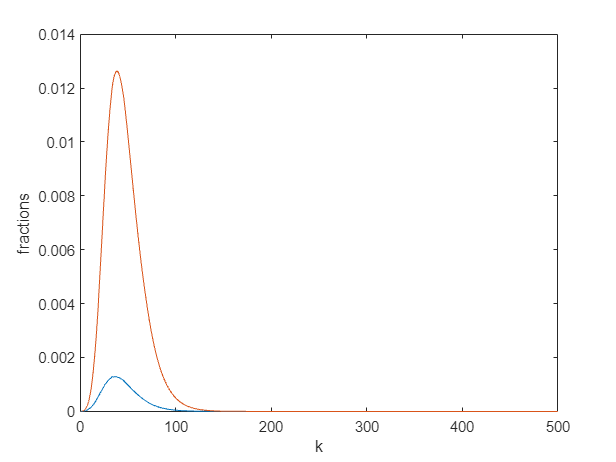

plot(ss_rslt.vfi_rslt.var_state.k, ss_rslt.dist);
xlabel('k');
ylabel('fractions');

and the policy functions

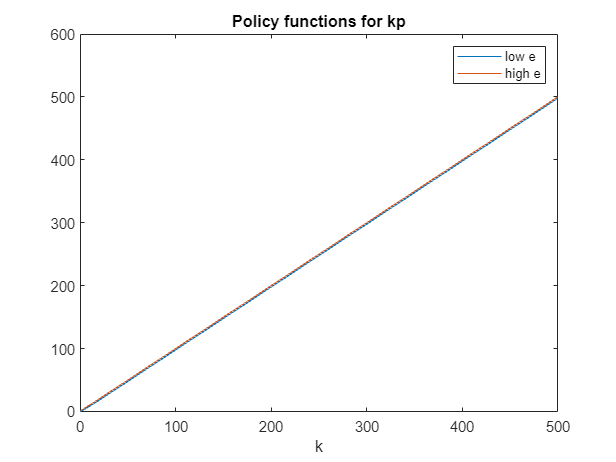

plot(ss_rslt.vfi_rslt.var_state.k, ss_rslt.vfi_rslt.var_policy.kp);
xlabel('k');
title('Policy functions for kp');
legend({'low e','high e'})

# Solve the Transition Path After A Temporay Shock

## Solve the linearized transition path

We first construct the sequence of productivity shock.

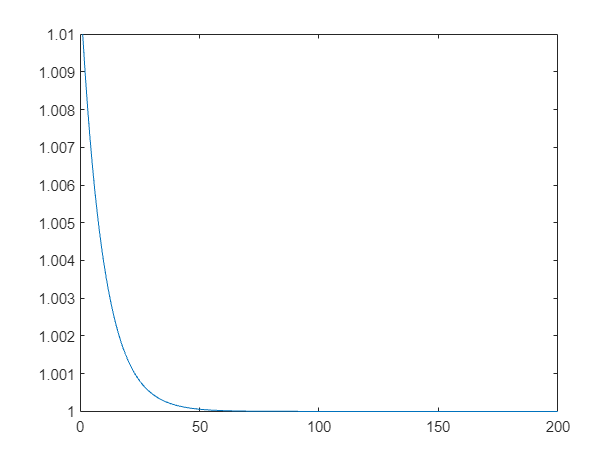

T = 200;
shock_z = 0.01; rho_z = 0.9;
z_t = 1 + shock_z *rho_z.^(0:(T-1));
figure;
plot(z_t)

We then pass the productivity shock and the solved ss_rslt into solve_trans_linear to solve the linearized transition path.

options = struct;
options.T = T;
options.z_t = z_t;
tic;
trans_linear_rslt = solve_trans_linear(ss_rslt, options);
fprintf('Time used for solving the linearized transition path:\n');toc;

Time used for solving the linearized transition path:
Elapsed time is 1.031445 seconds.


trans_linear_rslt

trans_linear_rslt = struct with fields:
             var_agg_t: [1×1 struct]
       var_agg_shock_t: [1×1 struct]
      jacs_ind_wrt_agg: {[200×200 double]  [200×200 double]}
    jac_eqs_of_var_agg: [200×200 double]
               irf_ssj: [200×200 double]

We can plot the transition path (note that K is the next period capital).

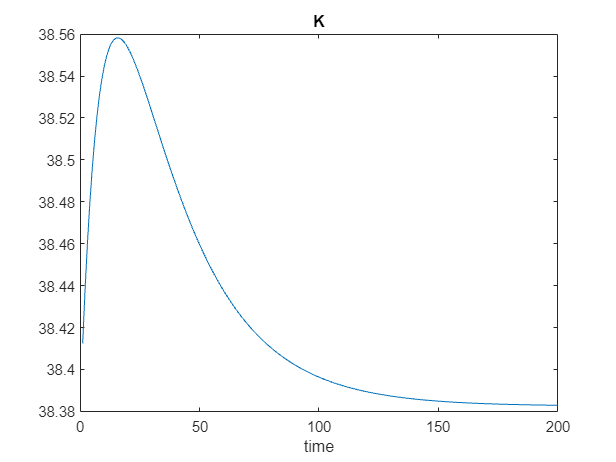

figure;
plot(trans_linear_rslt.var_agg_t.K)
title('K');
xlabel('time');